**Physical setting**

car = [];
car.M_total = 2149;
car.g = 9.81;
car.m_wheel = 30.556;
car.r_wheel = 0.32985;
car.Cd = 0.23;
car.V_desire = 27.778;
car.wide = 1.849;
car.height = 1.443;
car.rho_air = 1.17;
car.A = car.height * car.wide;
car.Gr = 14;
car.beta = car.rho_air*car.A*car.Cd/2;
car.I_wheel = 0.5*car.m_wheel*car.r_wheel^2;
motor = [];
motor.R = 3.04;
motor.L = 0.104;
motor.J = 0.06;
motor.kt = 1.86;
motor.ki = 1.86;
ieff = (2*car.I_wheel/car.r_wheel)+(motor.J*car.Gr^2/car.r_wheel)+2*car.m_wheel*car.r_wheel+(car.M_total-2*car.m_wheel)*car.r_wheel;

**Design criteria**

overshoot<10%

rise time <6s

settling time<10s

**Transfer Function**

T2V = tf(1,[ieff 2*car.beta*car.r_wheel*car.V_desire]);
T2VD = [ieff 2*car.beta*car.r_wheel*car.V_desire];
E2TD = car.r_wheel*conv([motor.L motor.R],[ieff 2*car.beta*car.r_wheel*car.V_desire])+[0 0 motor.ki*motor.kt*car.Gr^2];
E2TN = car.r_wheel*car.Gr*motor.kt*[ieff 2*car.beta*car.r_wheel*car.V_desire];
E2T = tf(E2TN,E2TD);
dragstar = 2*car.beta*car.r_wheel*car.V_desire^2;
Tstar = car.beta*car.r_wheel*car.V_desire^2;
disturb = Tstar - dragstar;
E2V = tf(motor.kt*car.Gr*car.r_wheel,E2TD);
sisotool(E2V)

**2D Animation**

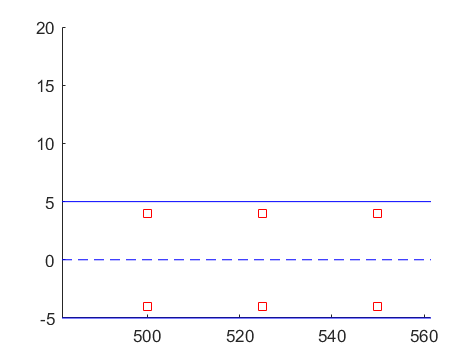

out = sim("animation.slx");
n = length(out.tout);
i = 1;
t0 = 0;
cla;
hold on
plot(0:25:1000,ones(41)*4,"s", 'Color',"r")
plot(0:25:1000,ones(41)*-4,"s", 'Color',"r")
plot([0 1000], [5 5], 'Color', 'blue')
plot([0 1000], [0 0],'--', 'Color', 'blue')
plot([0 1000], [-5 -5], 'Color', 'blue')
for t = 0:1:(n-1)
    x_car = out.displace(i);
    p_car_up = plot(linspace(x_car-4,x_car+4,10),ones(10),"b-");
    p_car_down = plot(linspace(x_car-4,x_car+4,10),ones(10)*-1,"b-");
    p_car_left = plot(ones(10)*(x_car-4),linspace(-1,1,10),"b-");
    p_car_right = plot(ones(10)*(x_car+4),linspace(-1,1,10),"b-");
    p_center = plot(x_car,0,"bo");
    disp_vel = text(x_car+20,15,num2str(out.velocity(i))+" m/s");
    axis([x_car-40 x_car+40 -5 20])
    tdiff = out.tout(i) - t0;
    t0 = out.tout(i);
    pause(tdiff)
    i = i + 1;
    delete(disp_vel)
    delete(p_center)
    delete(p_car_up)
    delete(p_car_down)
    delete(p_car_left)
    delete(p_car_right)
end
hold off